% Paramètre live script 
    clear;
    [simulation, physics, thrusters, mpc] = ConfigAUV8()

simulation = struct with fields:
    reference_frame: [119 111 114 108 100]
         model_name: [97 117 118 56]


physics = struct with fields:
             mass: 33.9500
           volume: 0.0370
              rho: 998
                g: 9.8100
    dvlCenterDist: 0.1435
           height: 0.3000
                I: [3×3 double]
               RG: [1.0000e-03 -0.0030 0.0270]
               RB: [0 0 -0.1000]
              CDL: [45 60 70 10 7 15]
              CDQ: [1.1700 0.8200 0.7560 0.1670 0.1000 0.1020]
               AF: [0.1200 0.2200 0.2920]
        AddedMass: [0 0 0 0 0 0]


thrusters = struct with fields:
    T: [8×6 double]


mpc = struct with fields:
       nx: 13
       ny: 13
       nu: 8
       Ts: 0.2500
        p: 4
        m: 2
     tmax: 29
     tmin: -24
    gains: [1×1 struct]


    sympref('MatrixWithSquareBrackets',true);

## Constantes du modèle physique

### Masse ajoutée avec des prismes à base ovale

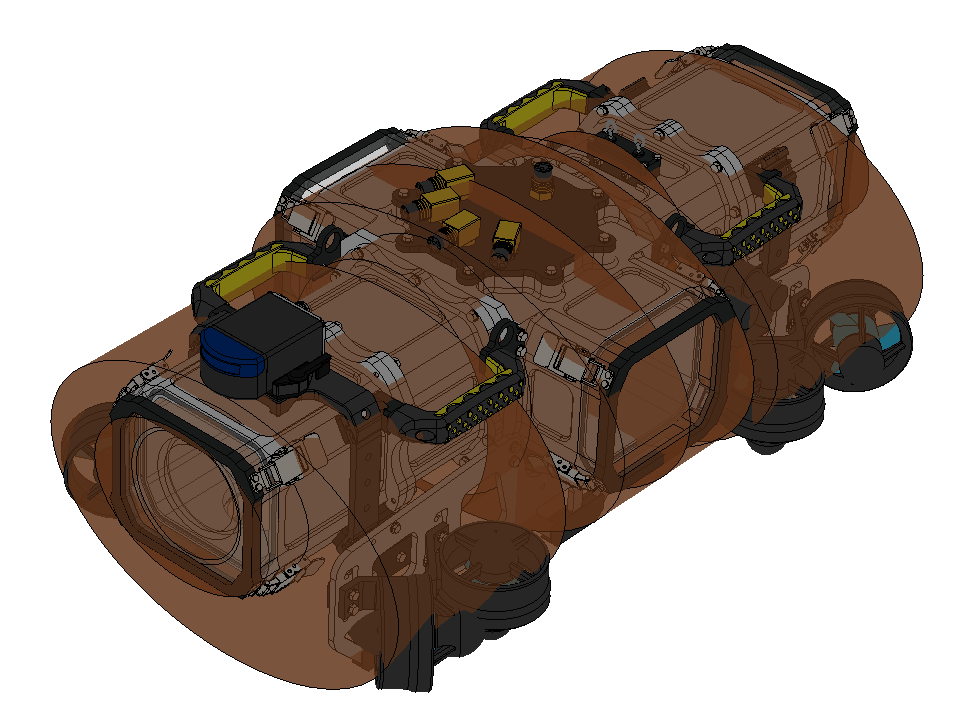

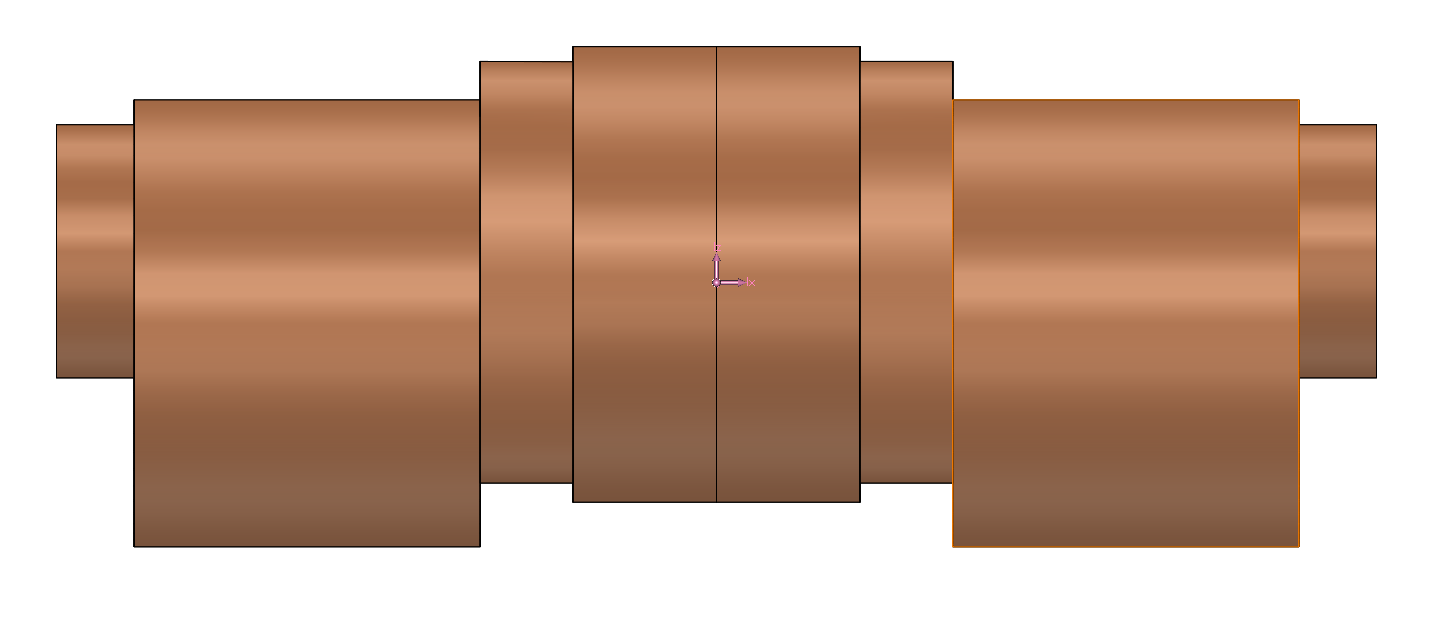

% TO-DO - Vérifier la taille des ovals.
% Paramètres
        % a     b     x
ovals = [0.15, 0.2, 0.046;
         0.265, 0.4, 0.205;
         0.25, 0.225, 0.055;
         0.27, 0.43, 0.085];

% Coefficients pour la masse ajoutée.
Y_u_dot = 0;
Z_w_dot = 0;
K_p_dot = 0;

A11 = 0.1 * physics.rho * physics.volume

A11 = 3.6926


for i = 1: size(ovals, 1)
    Y_u_dot = Y_u_dot + (pi * physics.rho * (ovals(i, 1)/2)^2) * ovals(i, 3);
    Z_w_dot = Z_w_dot + (pi * physics.rho * (ovals(i, 2)/2)^2) * ovals(i, 3);
    K_p_dot = K_p_dot + (1/8) * pi * physics.rho * ((ovals(i, 2)/2)^2 - (ovals(i, 1)/2)^2)^2 * ovals(i, 3);
end

Y_u_dot = Y_u_dot * 2;
Z_w_dot = Z_w_dot * 2;
K_p_dot = K_p_dot * 2;

disp(Y_u_dot);

   39.2935



disp(Z_w_dot);

   83.3065



disp(K_p_dot);

    0.1342



clear;
[simulation, physics, thrusters, mpc] = ConfigAUV8()

simulation = struct with fields:
    reference_frame: [119 111 114 108 100]
         model_name: [97 117 118 56]


physics = struct with fields:
             mass: 33.9500
           volume: 0.0370
              rho: 998
                g: 9.8100
    dvlCenterDist: 0.1435
           height: 0.3000
                I: [3×3 double]
               RG: [1.0000e-03 0.0020 0.0180]
               RB: [0 0 -0.1000]
              CDL: [45 60 70 10 7 15]
              CDQ: [1.1700 0.8200 0.7560 0.1670 0.1000 0.1020]
               AF: [0.1200 0.2200 0.2920]
        AddedMass: [1.4648 12.6156 12.6156 0.1164 0.3493 0]


thrusters = struct with fields:
    T: [8×6 double]


mpc = struct with fields:
       nx: 13
       ny: 13
       nu: 8
       Ts: 0.2500
        p: 4
        m: 2
     tmax: 29
     tmin: -24
    gains: [1×1 struct]


### Masse ajoutée avec éllipsoide

### 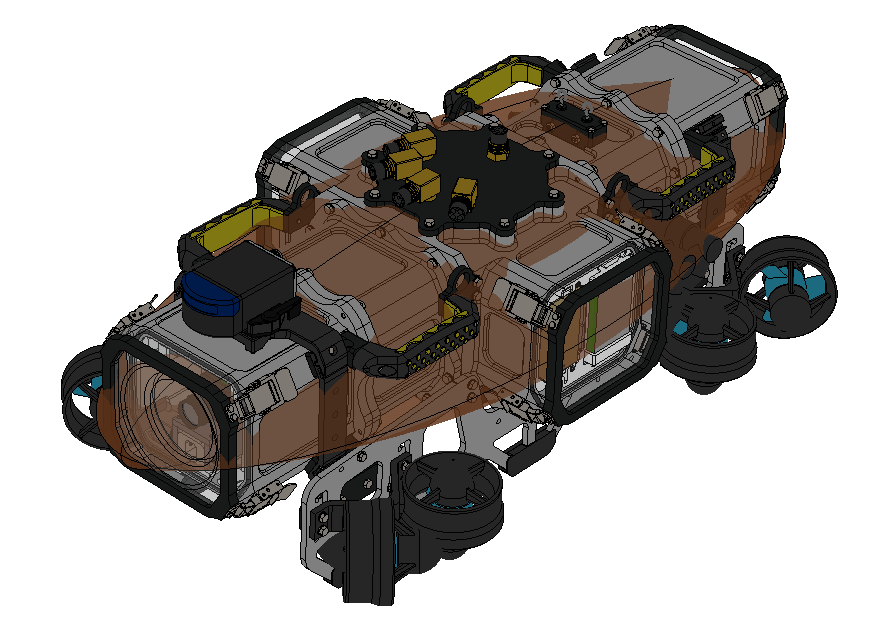

% Coefficients pour la masse ajoutée.
a = (0.89)/2;
b = 0.18/2;
c = 0.175;
e = 1 - (b/a)^2

e = 0.9591

beta_0 = (1/e^2) - ((1-e^2)/(2 * e^3))*log((1+e)/(1-e))

beta_0 = 0.9114

alpha_0 = ((2*(1-e^2))/e^3)*(0.5*log((1+e)/(1-e))-e)

alpha_0 = 0.1772

m = (4/3)* pi * physics.rho * a * b^2

m = 15.0683


X_u_dot = -(alpha_0/(2 - alpha_0))*m

X_u_dot = -1.4648

Y_v_dot = -(beta_0/(2 - beta_0))*m

Y_v_dot = -12.6156

Z_w_dot = Y_v_dot * 1.25

Z_w_dot = -15.7695

M_q_dot = -(1/5)*(((b^2-a^2)^2*(alpha_0-beta_0))/(2*(b^2-a^2)+(b^2+a^2)*(beta_0-alpha_0)))*m

M_q_dot = -0.3493

N_r_dot = M_q_dot

N_r_dot = -0.3493

K_p_dot = M_q_dot / 3

K_p_dot = -0.1164